### Load cell masks, tracks, and fits 

        select folder

        set pixel size

Open_folder = uigetdir('L:\MIGRATED\Lab_Members\Xiaofeng_Dai\Manuscript\Nucleoid_Viscosity\Dataset');

pixel_size = 49;    %pixel size in nm
[Store_mask,Store_track,Store_fits,result_folder]=...
    DataLoader(Open_folder);

Error using DataLoader (line 26)
The input dataFolder must be a character vector or string.

### Visualize cell morphology distributions

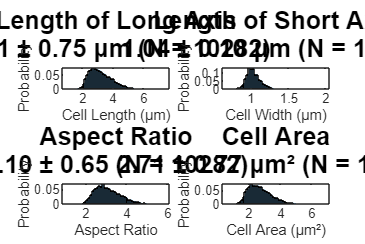

[cell_morph, morph_by_mov] = CalMorph(pixel_size, Store_mask, 'on');
SaveFigure(result_folder,...
    'Cell Morphology Distribution',gcf,...
    {'fig','png','svg'},'parula')


% % quantile of cell morphology distribution
% quantile(cell_morph(:,sel_filter),[0.2, 0.8])

### Set up parameters and filter based on morphology

        set up num of pixels in y axis

        choose which morphology as filter

        set up boundaries for cellMorphFilter

num_pix_y = 20;
sel_filter = 2;

% opt1: lower and upper bounds based on mean value and std
low_bd = mean(cell_morph(:,sel_filter))-min(0.5,std(cell_morph(:,sel_filter)))

low_bd = 2.7115

up_bd  = mean(cell_morph(:,sel_filter))+min(0.5,std(cell_morph(:,sel_filter)))

up_bd = 3.7115


% % opt2: quantile of cell morphology distribution
% q = quantile(cell_morph(:,sel_filter),...
%                             [0.725, 0.975]);
% low_bd = q(1)
% up_bd  = q(2)
% clear q

% opt3: manually set lower and upper bounds 
% low_bd = 2.0
% up_bd = 3.5

% Use morphology filter to select cells (cellIndices) and calculate the
% averaged aspect ratio of cells passing the filter
[aspt_ratio, cell_avg_width, cellIndices] = cellMorphFilter(sel_filter,...
    [low_bd, up_bd], cell_morph,...
    morph_by_mov, num_pix_y);

Mean aspect ratio = 3.06    ~3.05
Number of grids y axis = 20
Number of grids x axis = 61


fprintf('# cells passing morphology filter: %d. \n',length(cat(1,cellIndices{:})))

# cells passing morphology filter: 4872. 


### Calculate Localization fitting confidence interval 

[locFitCI, locFitCI_UB] = Loc_fitCI(Store_track, Store_fits, pixel_size, 'mean');

Mean localization Confidence Interval = 79.405 nm 


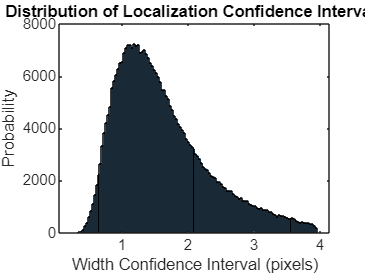

SaveFigure(result_folder,'Localization fitting CI',gcf,...
    {'fig','png','svg'},'parula')

% % Bootstrap sampling 
% bootstrp_list = Btstrp(cellIndices, 7000, 192, 42);
% Index = reorgIndex(bootstrp_list{1});

% use all cells 
Index = cellIndices;